# Test Ho-Kalman Algorithm

clear all; close all; clc;

## FLAGS

### HK Rank

- Using Rank, r = rank(S)

- All States from Hankel

- Number of States

- Number of short dynamics States

FLAG.HK_rank = 3;

### Adjust HK Input Magnitude

- No magnitude adjustment

- Simple order of magnitude !!!!!!!!! Not implemented

- Overall change is 1

FLAG.HK_AdjustMag = 3;

### Others

FLAG.Use_t_minus = 0; % 1 if the impulse occurs before t_impulse; 0 if impulse occurs after
FLAG.Use_Ind_ROM = 0; % 1 if using create ROM for each state, 0 if using a combined ROM

## Initial Parameters

Ts          = .1;             % [s], Sampling Rate
TsMultiple  = 5;             % Times in between samples (# of samples per sample)
TsSim       = Ts/TsMultiple; % Simulate with finer t_vec
N_steps_min = 50;            % Minimum number of steps to take

## Create State Space Systems

### A Matrix

N_dominate_dynam = 5; 
dominate_min = -2;
dominate_max = -1;
dominate_eig = logspace(dominate_min,dominate_max,N_dominate_dynam);

% N_nondom_dynam = 10-N_dominate_dynam;
N_nondom_dynam = 1;
%N_nondom_dynam = 100;
nondom_min = 1;
nondom_max = 2;
nondom_eig = logspace(nondom_min,nondom_max,N_nondom_dynam);

Aeig = -1*[dominate_eig , nondom_eig];
A = diag(Aeig);

### B Matrix

% B = zeros(length(A),1); B(1) = 1;
B = ones(length(A),1);

### C Matrix

C = eye(length(A));
%C = zeros(length(A)); C(1,1) = 1;

### D Matrix

D = zeros(length(C),1);

### Create Continuous Time State Space object

sys_CT = ss(A,B,C,D);

### Create Discrete Time State Space object

sys_DT = c2d(sys_CT,Ts);

### Determine Eigenvalues of System

[eig_vec, eig_val] = eig(sys_CT.A);
eig_val

eig_val =  -100.0000         0         0         0         0         0
         0   -0.1000         0         0         0         0
         0         0   -0.0562         0         0         0
         0         0         0   -0.0316         0         0
         0         0         0         0   -0.0178         0
         0         0         0         0         0   -0.0100


[U,S,V] = svd(A);
S

S =   100.0000         0         0         0         0         0
         0    0.1000         0         0         0         0
         0         0    0.0562         0         0         0
         0         0         0    0.0316         0         0
         0         0         0         0    0.0178         0
         0         0         0         0         0    0.0100


[eig_vec_DT, eig_val_DT] = eig(sys_DT.A);
eig_val_DT

eig_val_DT =     0.0000         0         0         0         0         0
         0    0.9900         0         0         0         0
         0         0    0.9944         0         0         0
         0         0         0    0.9968         0         0
         0         0         0         0    0.9982         0
         0         0         0         0         0    0.9990


[U_DT,S_DT,V_DT] = svd(sys_DT.A);
S_DT

S_DT =     0.9990         0         0         0         0         0
         0    0.9982         0         0         0         0
         0         0    0.9968         0         0         0
         0         0         0    0.9944         0         0
         0         0         0         0    0.9900         0
         0         0         0         0         0    0.0000


## Create Time Vectors

% Ensure minimal relaxtion times
if 2*length(A) < N_steps_min
    t_final = N_steps_min * Ts;
else
    t_final = 2*length(A)*Ts;
end

% Continuous time vector
t_vec_ode = 0:TsSim:t_final

t_vec_ode =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


% Discrete time vector
t_vec_DT  = 0:Ts:t_final

t_vec_DT =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


## Create Impulse Current Profile

### Get Input Profile for ODE simulation

% Initialize
current = zeros(size(t_vec_ode));

Set the values of the impulse to one

    The profile goes as follows:

- Relax for Ts

- Impulse for Ts

- Relax for the remainer of the time

if FLAG.Use_t_minus
    idx = TsMultiple+1:1:2*TsMultiple;
else
    idx = TsMultiple+2:1:2*TsMultiple+1;
end
current(idx) = ones(size(idx));

% Insert Rising and Falling Ramp Times
if FLAG.Use_t_minus
    ImpulseCurrentProfile.t = [t_vec_ode(1:TsMultiple) , Ts-Ts/50 , t_vec_ode(TsMultiple+1:2*TsMultiple) , 2*Ts-Ts/50 , t_vec_ode(2*TsMultiple+1:end)]';
    ImpulseCurrentProfile.u = [  current(1:TsMultiple) , 0        ,   current(TsMultiple+1:2*TsMultiple) , 1          ,   current(2*TsMultiple+1:end)]';
else
    ImpulseCurrentProfile.t = [t_vec_ode(1:TsMultiple+1) , Ts+Ts/50 , t_vec_ode(TsMultiple+2:2*TsMultiple+1) , 2*Ts+Ts/50 , t_vec_ode(2*TsMultiple+2:end)]';
    ImpulseCurrentProfile.u = [  current(1:TsMultiple+1) , 1        ,   current(TsMultiple+2:2*TsMultiple+1) , 0          ,   current(2*TsMultiple+2:end)]';
end

% Create discrete time current profile
ImpulseCurrentProfile_DT.t = t_vec_DT';
current = zeros(size(t_vec_DT)); 
current(2) = 1;
ImpulseCurrentProfile_DT.u = current';

### Plot the impulse data

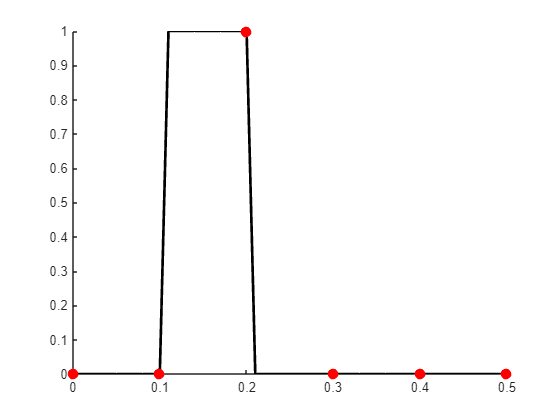

% Interpolate the input profile with desired times
t_vec = 0:Ts/10:(5*Ts); %%%%%%%%!!!!!Hardcoded
u_vec = interp1(ImpulseCurrentProfile.t , ImpulseCurrentProfile.u , t_vec);
u_vec_DT = interp1(ImpulseCurrentProfile.t , ImpulseCurrentProfile.u , ImpulseCurrentProfile_DT.t(1:6));%%%%%%%%!!!!!Hardcoded

figure
hold on
plot(t_vec,u_vec,'k','Linewidth',2)
plot(ImpulseCurrentProfile_DT.t(1:6) , u_vec_DT,'ro','MarkerFaceColor','r','Linewidth',2)%%%%%%%%!!!!!Hardcoded

## Run Impulse ODE

tspan = t_vec_ode;
SV_IC = zeros(length(A),1);

% Simulation Parameters
Tol.Abs = 1E-7;
Tol.Rel = 1E-7;

options = odeset('RelTol' ,Tol.Rel,      ...
                 'AbsTol' ,Tol.Abs,      ...
                 'MaxStep',(.99)*Ts); %%%%%%%%%% This is inplace so it doesn't skip the impulse

SOLN = ode15s(@(t,x)odeFun(t,x,sys_CT,ImpulseCurrentProfile) , tspan , SV_IC , options);

SOLN_ODE.t = t_vec_ode;             % Time
SOLN_ODE.x = deval(SOLN,t_vec_ode); % States

SOLN_DT.t  = t_vec_DT;             % Time
SOLN_DT.x  = deval(SOLN,t_vec_DT); % States

#### Test Plot Just Simulated Results

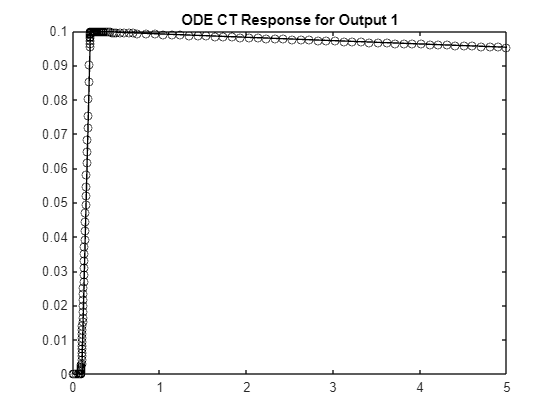

if 1
figure
plot(SOLN.x,SOLN.y(1,:),'-ok','DisplayName','ODE')
title('ODE CT Response for Output 1')
end

#### Test Plot DT with CT Simulated

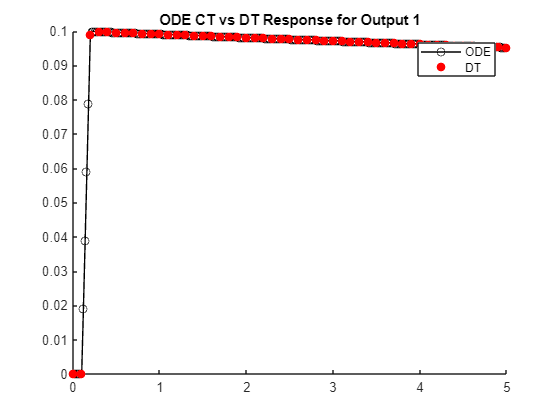

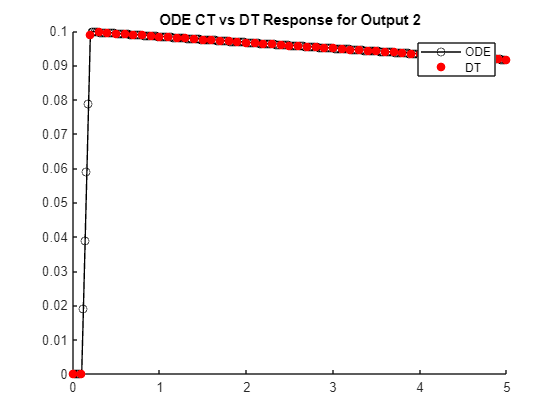

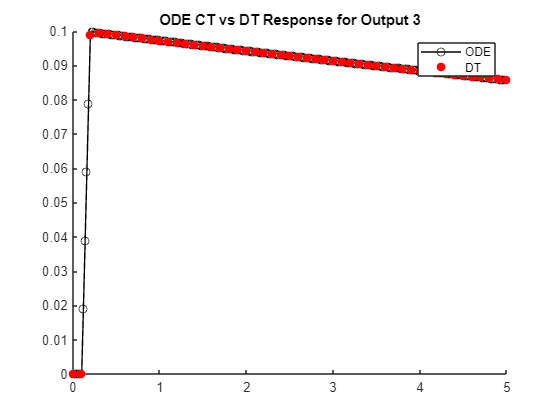

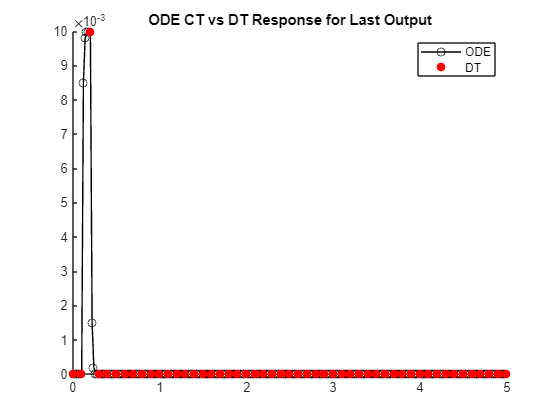

if 1
figure
hold on
plot(SOLN_ODE.t,SOLN_ODE.x(1,:),'-ok','DisplayName','ODE')
plot( SOLN_DT.t ,SOLN_DT.x(1,:) ,'or','MarkerFaceColor','r' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 1');

figure
hold on
plot(SOLN_ODE.t,SOLN_ODE.x(2,:),'-ok','DisplayName','ODE')
plot( SOLN_DT.t ,SOLN_DT.x(2,:) ,'or','MarkerFaceColor','r' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 2');

figure
hold on
plot(SOLN_ODE.t,SOLN_ODE.x(3,:),'-ok','DisplayName','ODE')
plot( SOLN_DT.t ,SOLN_DT.x(3,:) ,'or','MarkerFaceColor','r' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 3');

figure
hold on
plot(SOLN_ODE.t,SOLN_ODE.x(end,:),'-ok','DisplayName','ODE')
plot( SOLN_DT.t ,SOLN_DT.x(end,:) ,'or' ,'MarkerFaceColor','r','DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Last Output');
end

## Perform Ho-Kalman

% max_idx = length(t_final);
% 1;
ImpulseData_All.t = SOLN_ODE.t;
ImpulseData_All.x = SOLN_ODE.x;
ImpulseData = C * SOLN_DT.x;
% [sys_HK] = getHoKalmanROM(ImpulseData_All , ImpulseData , SOLN_DT.t , Ts , N_dominate_dynam , FLAG); 
%%%%%%!!!! Normally I use this function call but not in live script

## Start of Ho-Kalman Algorithm

%% Initialize
    if FLAG.Use_t_minus
        start_idx = 1;
    else
        start_idx = 2;
    end
    [N_out,N_steps] = size(ImpulseData);


### Modify Incoming Impulse Data

    %% Sort Data for g_k        
        z_imp    = ImpulseData;
        g_k_temp = z_imp(:,start_idx:end);
        %g_k_temp = z_imp(:,idx_vec(pulse_idx:end));    % t^-
        IC       = z_imp(:,1)

IC =      0
     0
     0
     0
     0
     0


        g_k      = g_k_temp - g_k_temp(:,1)

g_k =          0    0.0990    0.0999    0.0998    0.0997    0.0996    0.0995    0.0994    0.0993    0.0992    0.0991    0.0990    0.0989    0.0988    0.0987    0.0986    0.0985    0.0984    0.0983    0.0982    0.0981    0.0980    0.0979    0.0978    0.0977    0.0976    0.0975    0.0974    0.0973    0.0972    0.0971    0.0970    0.0969    0.0968    0.0967    0.0966    0.0965    0.0964    0.0963    0.0962    0.0961    0.0960    0.0959    0.0958    0.0957    0.0956    0.0956    0.0955    0.0954    0.0953
         0    0.0989    0.0997    0.0996    0.0994    0.0992    0.0990    0.0989    0.0987    0.0985    0.0983    0.0982    0.0980    0.0978    0.0976    0.0975    0.0973    0.0971    0.0969    0.0968    0.0966    0.0964    0.0963    0.0961    0.0959    0.0957    0.0956    0.0954    0.0952    0.0951    0.0949    0.0947    0.0946    0.0944    0.0942    0.0941    0.0939    0.0937    0.0936    0.0934    0.0932    0.0931    0.0929    0.0927    0.0926    0.0924    0.0922    0.0921    0.0919   

        %% Adjust for Order of Magnitude
        disp(['Min of g_k is :' num2str(min(g_k'))])

Min of g_k is :0           0           0           0           0 -8.0454e-08


        disp(['Max of g_k is :' num2str(max(g_k'))])

Max of g_k is :0.099851    0.099736     0.09953    0.099166    0.098522   0.0099994


        switch FLAG.HK_AdjustMag
            case 1 % No Adjustment
                g_k = g_k;
                multiple = eye(N_out);
            case 2 %Simple order of magnitude
%                 Multiple = ones(N_out,1)
%                 for i = 1:N_out
%                     i
%                     min(abs(g_k(i,:))')<0.1 
%                     max(abs(g_k(i,:))')>1
%                     while min(abs(g_k(i,:))')<0.1  max(abs(g_k(i,:))')>1
%                         min_gk = min(abs(g_k(i,:))')';
%                         max_gk = max(abs(g_k(i,:))')';
%                         if min_gk < 0.1
%                             Multiple(i) = Multiple(i)*10;
%                             g_k(i,:) = g_k(i,:)*10;
%                         end
%                         if max_gk > 1
%                             Multiple(i) = Multiple(i)/10;
%                             g_k(i,:) = g_k(i,:)/10;
%                         end
%                     end
%                 end

            case 3
                y_range  = (max(g_k')-min(g_k'));
                g_k      = inv(diag(y_range))*g_k;
                multiple = diag(y_range);
        end
        multiple

multiple =     0.0999         0         0         0         0         0
         0    0.0997         0         0         0         0
         0         0    0.0995         0         0         0
         0         0         0    0.0992         0         0
         0         0         0         0    0.0985         0
         0         0         0         0         0    0.0100


        disp(['Min of g_k is :' num2str(min(g_k'))])

Min of g_k is :0           0           0           0           0 -8.0458e-06


        disp(['Max of g_k is :' num2str(max(g_k'))])

Max of g_k is :1           1           1           1           1     0.99999


%         min_gk = min(g_k')'
%         max_gk = max(g_k')'
        g_k

g_k =          0    0.9910    1.0000    0.9990    0.9980    0.9970    0.9960    0.9950    0.9940    0.9930    0.9920    0.9910    0.9900    0.9891    0.9881    0.9871    0.9861    0.9851    0.9841    0.9831    0.9822    0.9812    0.9802    0.9792    0.9782    0.9773    0.9763    0.9753    0.9743    0.9734    0.9724    0.9714    0.9704    0.9695    0.9685    0.9675    0.9666    0.9656    0.9646    0.9637    0.9627    0.9618    0.9608    0.9598    0.9589    0.9579    0.9570    0.9560    0.9550    0.9541
         0    0.9918    1.0000    0.9982    0.9964    0.9947    0.9929    0.9911    0.9894    0.9876    0.9859    0.9841    0.9824    0.9806    0.9789    0.9771    0.9754    0.9737    0.9719    0.9702    0.9685    0.9668    0.9651    0.9633    0.9616    0.9599    0.9582    0.9565    0.9548    0.9531    0.9514    0.9497    0.9480    0.9464    0.9447    0.9430    0.9413    0.9397    0.9380    0.9363    0.9347    0.9330    0.9313    0.9297    0.9280    0.9264    0.9247    0.9231    0.9215   

        %t_imp = t_impulse(start_idx:end);
        t_imp = SOLN_DT.t(start_idx:end)

t_imp =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


### Plot the Impulse Response Data

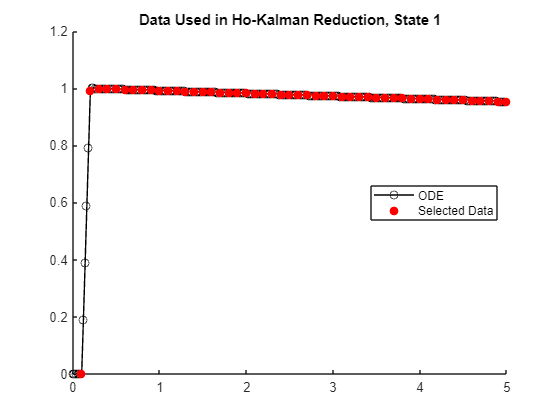

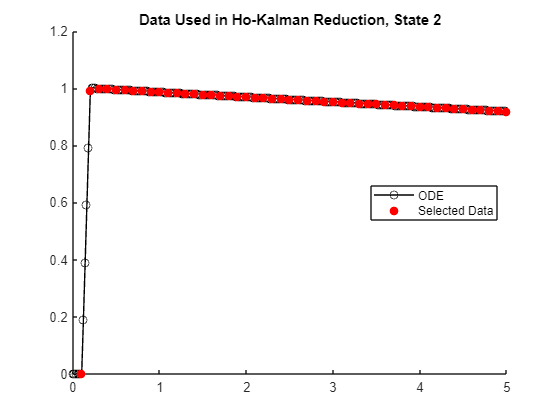

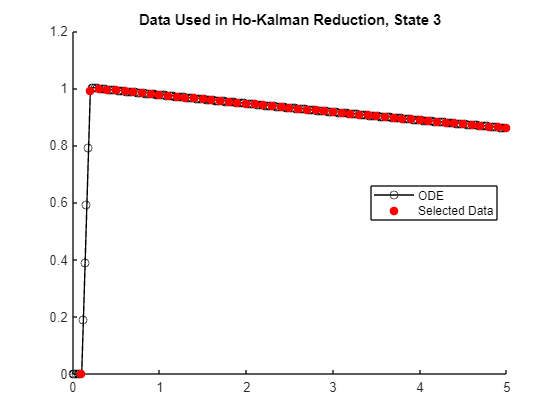

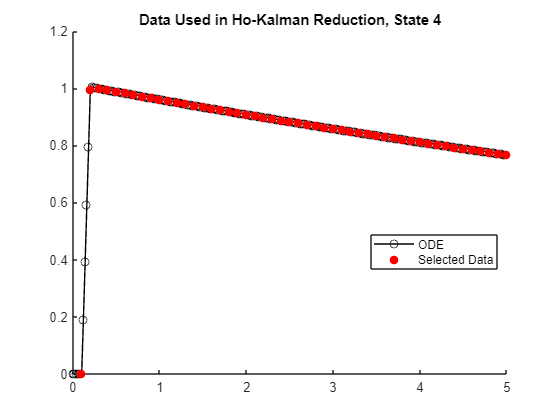

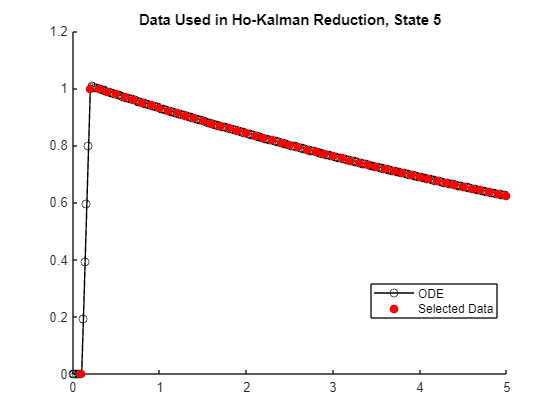

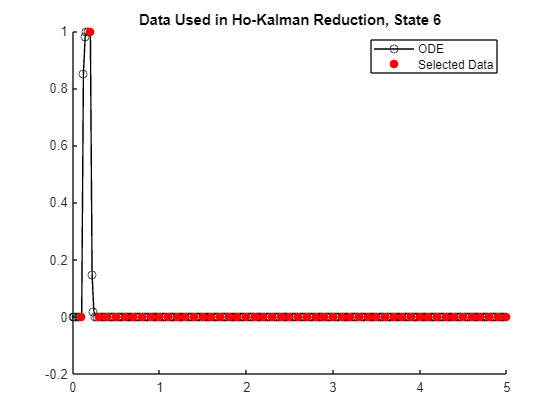

    %% Plot Impulse Response
        if 1
            for i = 1:N_out
            %for i = [1,2,3,10]
                figure
                hold on
                %plot(ImpulseData_All.t , ImpulseData_All.x(i,:) ,'-ok'                      ,'DisplayName','ODE')
                plot(ImpulseData_All.t , ImpulseData_All.x(i,:)/multiple(i,i) ,'-ok'                      ,'DisplayName','ODE')
                plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp             , multiple(i,i)*g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp(idx_vec(pulse_idx:end),:)  ,g_k(i,:)+IC(i,1),'or','MarkerFaceColor','r') % t^-
                title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
                lgn = legend;
                lgn.Location = 'best';
            end
        end

### Zoomed Plot of Impulse Data

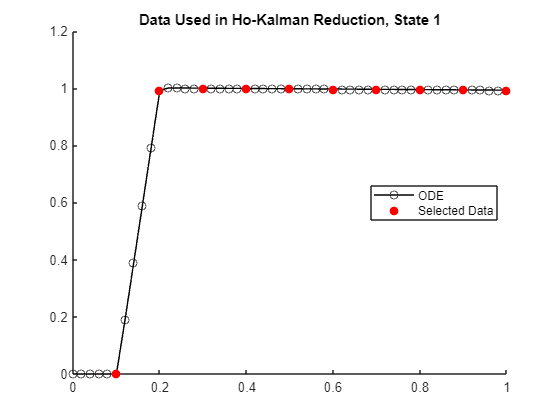

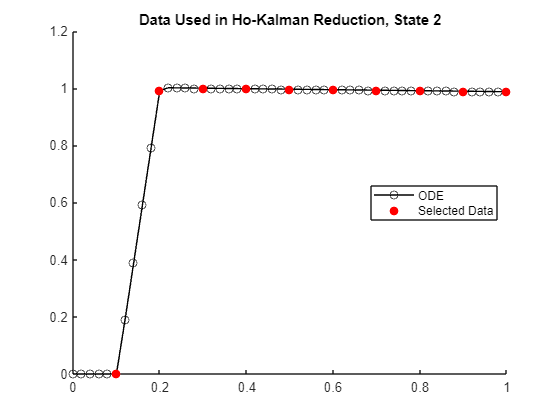

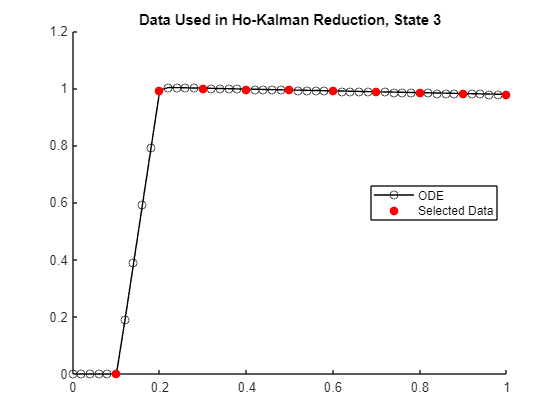

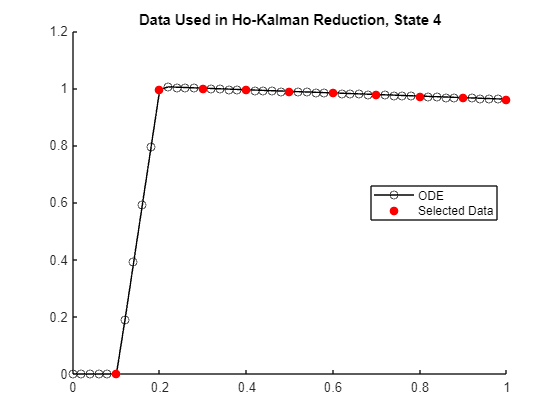

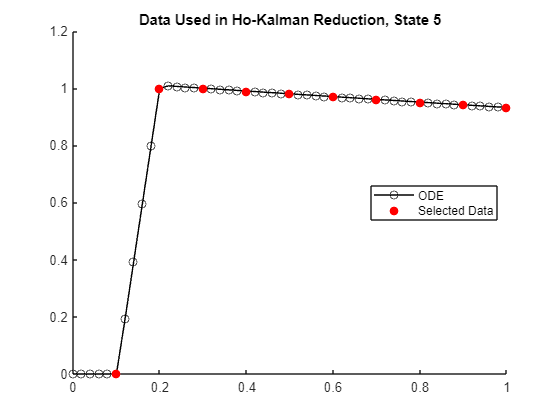

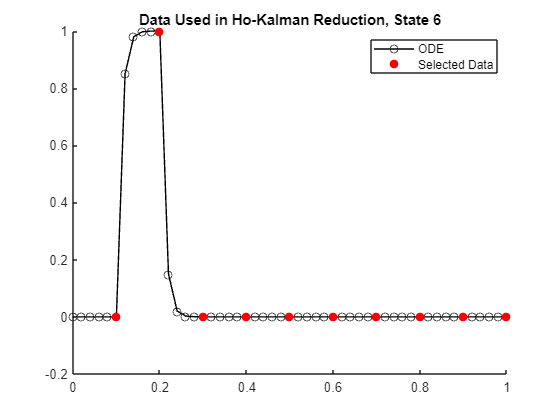

 %% Plot Impulse Response
        if 1
            for i = 1:N_out
            %for i = [1,2,3,10]
                figure
                hold on
                %plot(ImpulseData_All.t , ImpulseData_All.x(i,:) ,'-ok'                      ,'DisplayName','ODE')
                plot(ImpulseData_All.t , ImpulseData_All.x(i,:)/multiple(i,i) ,'-ok'                      ,'DisplayName','ODE')
                plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp             , multiple(i,i)*g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
                lgn = legend;
                lgn.Location = 'best';
                xlim([0,10*Ts])
            end
        end

if FLAG.Use_Ind_ROM
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Get ROM for each desired outputs separately (Combined with Voltage)
%     if N_out > Nrank
%         loop_end = Nrank+1;
%     else
%         loop_end = Nrank;
%     end
    if N_out > N_dominate_dynam
        loop_end = N_dominate_dynam+1; % Only want 1 of the non-dominate dynamics
    else
        loop_end = N_dominate_dynam;
    end

H =          0    0.9910    1.0000    0.9990    0.9980    0.9970    0.9960    0.9950    0.9940    0.9930    0.9920    0.9910    0.9900    0.9891    0.9881    0.9871    0.9861    0.9851    0.9841    0.9831    0.9822    0.9812    0.9802    0.9792    0.9782
         0    0.9918    1.0000    0.9982    0.9964    0.9947    0.9929    0.9911    0.9894    0.9876    0.9859    0.9841    0.9824    0.9806    0.9789    0.9771    0.9754    0.9737    0.9719    0.9702    0.9685    0.9668    0.9651    0.9633    0.9616
         0    0.9931    1.0000    0.9968    0.9937    0.9906    0.9874    0.9843    0.9812    0.9781    0.9750    0.9719    0.9689    0.9658    0.9628    0.9597    0.9567    0.9537    0.9507    0.9477    0.9447    0.9417    0.9387    0.9357    0.9328
         0    0.9956    1.0000    0.9944    0.9888    0.9833    0.9778    0.9723    0.9668    0.9614    0.9560    0.9506    0.9453    0.9400    0.9347    0.9295    0.9243    0.9191    0.9140    0.9088    0.9037    0.8987    0.8936    0.8886   

r = 6

U_colm =    -0.0929    0.4076    0.0170   -0.0100    0.0966    0.1032
   -0.0921    0.4035   -0.0020    0.0062    0.0193   -0.0528
   -0.0908    0.3963   -0.0351    0.0342   -0.0790   -0.1135
   -0.0886    0.3839   -0.0918    0.0816   -0.1361    0.1312
   -0.0848    0.3631   -0.1863    0.1588    0.1035   -0.0172
   -0.0041    0.0039   -0.6394   -0.7688   -0.0041    0.0005
   -0.0967    0.0043    0.0708   -0.0590    0.0960    0.0927
   -0.0959   -0.0005    0.0518   -0.0429    0.0187   -0.0631
   -0.0945   -0.0087    0.0189   -0.0151   -0.0793   -0.1236
   -0.0921   -0.0230   -0.0373    0.0319   -0.1358    0.1200


S_colm =    51.1136         0         0         0         0         0
         0    2.4012         0         0         0         0
         0         0    1.1794         0         0         0
         0         0         0    0.8098         0         0
         0         0         0         0    0.0076         0
         0         0         0         0         0    0.0000


V_colm =    -0.2010   -0.9764    0.0716   -0.0338   -0.0000   -0.0000
   -0.2090    0.0093   -0.7541   -0.6226   -0.0000    0.0000
   -0.2082    0.0183   -0.1921    0.3028    0.4110   -0.4263
   -0.2074    0.0207   -0.1699    0.2757    0.2932   -0.1830
   -0.2065    0.0230   -0.1479    0.2489    0.1878   -0.0034
   -0.2057    0.0254   -0.1262    0.2223    0.0947    0.1216
   -0.2049    0.0277   -0.1047    0.1961    0.0135    0.2011
   -0.2041    0.0300   -0.0835    0.1701   -0.0558    0.2412
   -0.2033    0.0323   -0.0624    0.1444   -0.1135    0.2476
   -0.2025    0.0345   -0.0416    0.1190   -0.1597    0.2264


S_sqrt =     7.1494         0         0         0         0         0
         0    1.5496         0         0         0         0
         0         0    1.0860         0         0         0
         0         0         0    0.8999         0         0
         0         0         0         0    0.0870         0
         0         0         0         0         0    0.0050


obsv_r =    -0.6638    0.6316    0.0185   -0.0090    0.0084    0.0005
   -0.6586    0.6252   -0.0022    0.0056    0.0017   -0.0003
   -0.6493    0.6141   -0.0381    0.0308   -0.0069   -0.0006
   -0.6334    0.5949   -0.0997    0.0734   -0.0118    0.0007
   -0.6064    0.5626   -0.2023    0.1429    0.0090   -0.0001
   -0.0292    0.0060   -0.6944   -0.6918   -0.0004    0.0000
   -0.6913    0.0066    0.0769   -0.0531    0.0083    0.0005
   -0.6856   -0.0007    0.0563   -0.0386    0.0016   -0.0003
   -0.6755   -0.0135    0.0206   -0.0136   -0.0069   -0.0006
   -0.6581   -0.0356   -0.0405    0.0287   -0.0118    0.0006


cont_r =    -1.4369   -1.4944   -1.4885   -1.4826   -1.4767   -1.4708   -1.4650   -1.4593   -1.4536   -1.4479   -1.4422   -1.4366   -1.4310   -1.4255   -1.4199   -1.4145   -1.4090   -1.4036   -1.3982   -1.3929   -1.3876   -1.3823   -1.3771   -1.3718   -1.3667
   -1.5130    0.0143    0.0283    0.0320    0.0357    0.0393    0.0429    0.0465    0.0500    0.0535    0.0569    0.0603    0.0637    0.0670    0.0703    0.0735    0.0768    0.0799    0.0831    0.0862    0.0893    0.0923    0.0953    0.0983    0.1012
    0.0778   -0.8189   -0.2086   -0.1845   -0.1607   -0.1371   -0.1137   -0.0906   -0.0678   -0.0452   -0.0229   -0.0008    0.0211    0.0427    0.0641    0.0853    0.1062    0.1269    0.1474    0.1677    0.1877    0.2075    0.2271    0.2465    0.2657
   -0.0304   -0.5602    0.2725    0.2481    0.2240    0.2001    0.1764    0.1531    0.1299    0.1070    0.0844    0.0620    0.0399    0.0179   -0.0037   -0.0252   -0.0464   -0.0674   -0.0882   -0.1087   -0.1290   -0.1491   -0.1690   -0.18

C_r =    -0.6638    0.6316    0.0185   -0.0090    0.0084    0.0005
   -0.6586    0.6252   -0.0022    0.0056    0.0017   -0.0003
   -0.6493    0.6141   -0.0381    0.0308   -0.0069   -0.0006
   -0.6334    0.5949   -0.0997    0.0734   -0.0118    0.0007
   -0.6064    0.5626   -0.2023    0.1429    0.0090   -0.0001
   -0.0292    0.0060   -0.6944   -0.6918   -0.0004    0.0000


B_r =    -1.4369
   -1.5130
    0.0778
   -0.0304
   -0.0000
   -0.0000


PP =    -0.6638    0.6316    0.0185   -0.0090    0.0084    0.0005
   -0.6586    0.6252   -0.0022    0.0056    0.0017   -0.0003
   -0.6493    0.6141   -0.0381    0.0308   -0.0069   -0.0006
   -0.6334    0.5949   -0.0997    0.0734   -0.0118    0.0007
   -0.6064    0.5626   -0.2023    0.1429    0.0090   -0.0001
   -0.0292    0.0060   -0.6944   -0.6918   -0.0004    0.0000
   -0.6913    0.0066    0.0769   -0.0531    0.0083    0.0005
   -0.6856   -0.0007    0.0563   -0.0386    0.0016   -0.0003
   -0.6755   -0.0135    0.0206   -0.0136   -0.0069   -0.0006
   -0.6581   -0.0356   -0.0405    0.0287   -0.0118    0.0006


PP_p =    -0.6913    0.0066    0.0769   -0.0531    0.0083    0.0005
   -0.6856   -0.0007    0.0563   -0.0386    0.0016   -0.0003
   -0.6755   -0.0135    0.0206   -0.0136   -0.0069   -0.0006
   -0.6581   -0.0356   -0.0405    0.0287   -0.0118    0.0006
   -0.6288   -0.0729   -0.1413    0.0969    0.0089   -0.0001
   -0.0281   -0.6301    0.0659   -0.0376   -0.0001    0.0003
   -0.6909    0.0003    0.0774   -0.0534    0.0083    0.0005
   -0.6846   -0.0070    0.0569   -0.0389    0.0016   -0.0003
   -0.6736   -0.0198    0.0211   -0.0139   -0.0069   -0.0006
   -0.6547   -0.0418   -0.0396    0.0281   -0.0118    0.0006


PP_inv =    -0.0131   -0.0130   -0.0128   -0.0124   -0.0118   -0.0006   -0.0141   -0.0140   -0.0137   -0.0134   -0.0127   -0.0010   -0.0141   -0.0139   -0.0137   -0.0133   -0.0126    0.0000   -0.0141   -0.0139   -0.0137   -0.0132   -0.0125   -0.0000   -0.0141   -0.0139   -0.0136   -0.0131   -0.0123    0.0000   -0.0140   -0.0139   -0.0136   -0.0131   -0.0122    0.0000   -0.0140   -0.0138   -0.0135   -0.0130   -0.0121    0.0000   -0.0140   -0.0138   -0.0135   -0.0129   -0.0120    0.0000   -0.0140   -0.0138
    0.2634    0.2606    0.2558    0.2475    0.2336    0.0025    0.0027   -0.0004   -0.0060   -0.0155   -0.0315   -0.2628    0.0001   -0.0031   -0.0086   -0.0180   -0.0338   -0.0000    0.0001   -0.0031   -0.0086   -0.0179   -0.0334    0.0000    0.0001   -0.0030   -0.0085   -0.0178   -0.0331    0.0000    0.0001   -0.0030   -0.0085   -0.0177   -0.0328   -0.0000    0.0001   -0.0030   -0.0085   -0.0176   -0.0325   -0.0000    0.0001   -0.0030   -0.0084   -0.0175   -0.0321    0.0000    0.0001

A_r =     0.9979    0.0397   -0.0045    0.0027    0.0000    0.0000
   -0.0455    0.0398    0.0928   -0.0639   -0.0000   -0.0000
   -0.0064    0.5819    0.5285   -0.3681   -0.0000   -0.0001
    0.0045    0.3253   -0.6247    0.4232   -0.0004   -0.0002
   -0.0012    0.0018   -0.0075   -0.0495    0.9949    0.0001
   -0.0001    0.0002    0.0019    0.0014    0.0297    0.9935


### Get Hankle Matrix (Individual)

    for OO = 1:loop_end
        H = myHankle(g_k(OO,:)); %%%%%%%%%%%%%See other live script

### Convert Hankel to DT SS

#### Determine Number of Inputs and Outputs

        [Nrows, Ncolms] = size(H);
        N_outputs = Nrows/Ncolms;
        N_in = 1; %%% !!! Hardcoded but always true for batteries

#### SVD of Hankle

        [U,S,V] = svd(H);

#### Determine Rank

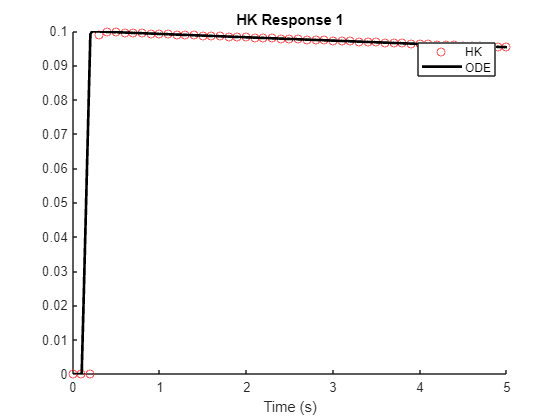

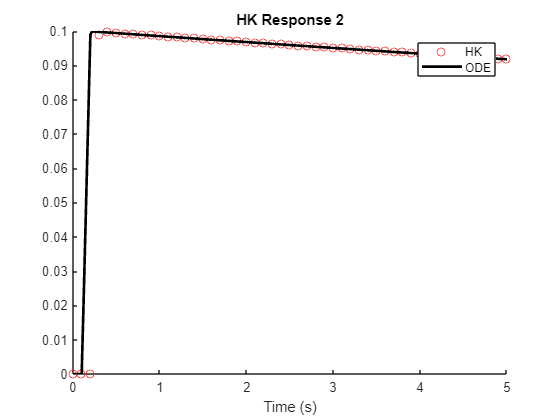

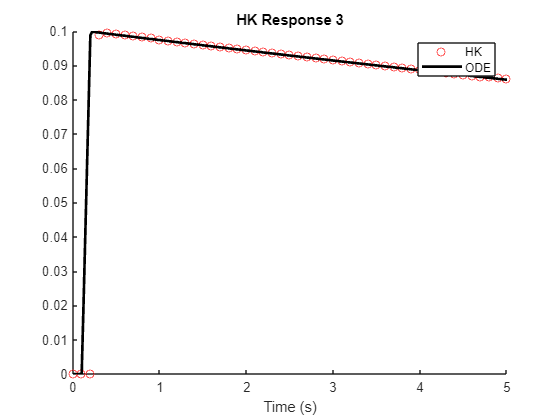

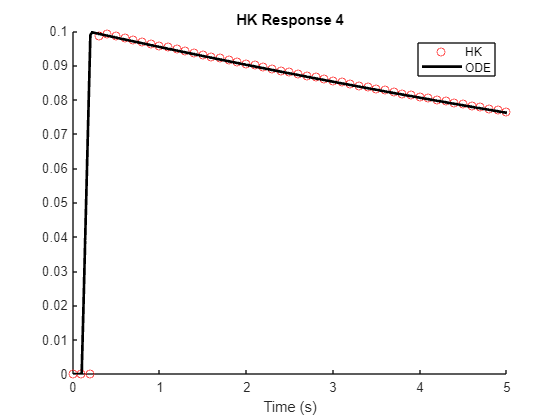

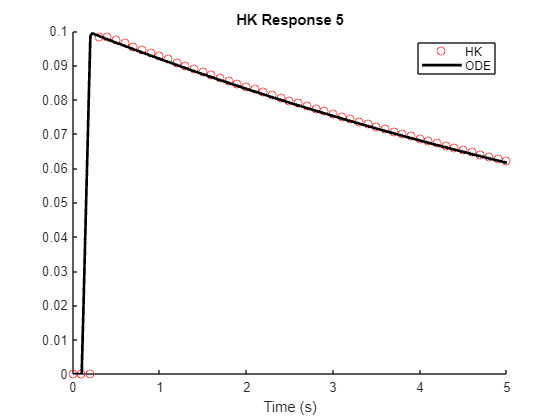

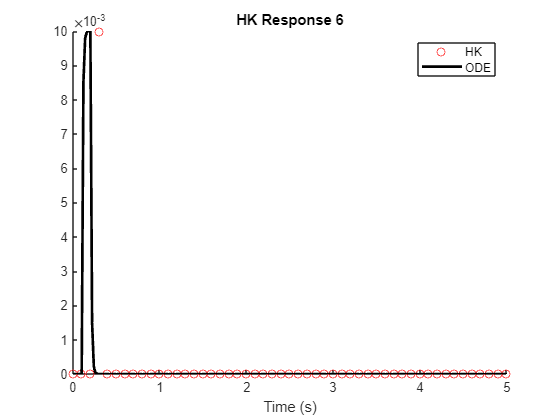

        switch FLAG.HK_rank
            case 1
                r = rank(S);
            case 2
                r = Ncolms;
            case 3
                r = N_out;
            case 4
                %r = Nrank;
                r = N_dominate_dynam;
        end
        %r = 2;
        r

        %singVals(OO) = S(r,r);


        U_colm = U(:,1:r)
        S_colm = S(1:r,1:r)

Eigenvalue Comparison


        V_colm = V(:,1:r)

---------------------


#### Extract Observability and Controllability

        % Balanced Reduction

Eig(A_DT)


        S_sqrt = S_colm.^0.5

4.54e-05
 0.99005
 0.99439
 0.99684
 0.99822
   0.999


        obsv_r = U_colm*S_sqrt
        cont_r = S_sqrt*V_colm'

2.5397e-05+0.0010271i             0+0i                             0+0i                     0+0i                     0+0i                     0+0i
         0+0i            2.5397e-05-0.0010271i                     0+0i                     0+0i                     0+0i                     0+0i
         0+0i                     0+0i                        0.9979+0i                     0+0i                     0+0i                     0+0i
         0+0i                     0+0i                             0+0i               0.99748+0i                     0+0i                     0+0i
         0+0i                     0+0i                             0+0i                     0+0i               0.99084+0i                     0+0i
         0+0i                     0+0i                             0+0i                     0+0i                     0+0i               0.99143+0i


#### Extract the SS matricies

        % C_r
        C_r = obsv_r(1:N_outputs,:   )
        C_r = multiple(OO,OO) * C_r

        % B_r
        B_r = cont_r(:        ,N_in)

        % A_r
        PP   = obsv_r(1:end-N_outputs,:)
        PP_p = obsv_r(N_outputs+1:end,:)
        threshold = 1e-7;
        PP_inv = pinv(PP,threshold)
        A_r = PP_inv*PP_p

        % D_r ~ !!!!! I'm assuming this is correct
        D_r = zeros(N_outputs,N_in)

%             if FLAG.PlotSingVal
%                 figure
%                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
%                 xlim([0,length(diag(S))])
%                 ylabel('Singular Values')
%                 title([RESULTS.Labels.title{OO} ' Singular Values of \Sigma for Hankel'])
%             end


        %% Return the system
        sys_HK{OO} = ss(A_r, B_r, C_r, D_r, Ts);
    end

else
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Get ROM for all desired outputs combined

### Get Hankle Matrix (Combined)

            %% Get Hankle Matrix
            H = myHankle(g_k) %%%%%%%%%%%%%See other live script    

### Convert Hankel to DT SS

#### Determine Number of Inputs and Outputs

            [Nrows, Ncolms] = size(H);
            N_outputs = Nrows/Ncolms;
            N_in = 1; %%% !!! Hardcoded but always true for batteries

#### SVD of Hankle

            [U,S,V] = svd(H);

#### Determine Rank

            switch FLAG.HK_rank
                case 1
                    r = rank(S);
                case 2
                    r = Ncolms;
                case 3
                    r = N_out;
                case 4
                    r = Nrank;
            end
            r
            
            %singVals = S(r,r)
    
            U_colm = U(:,1:r)
            S_colm = S(1:r,1:r)
            V_colm = V(:,1:r)

#### Extract Observability and Controllability

            % Balanced Reduction
            S_sqrt = S_colm.^0.5
            obsv_r = U_colm*S_sqrt
            cont_r = S_sqrt*V_colm'

#### Extract the SS matricies


$$\mathcal{O}=$$

$$\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\vdots \\
{\textrm{CA}}^{N-1} 
\end{array}\right\rbrack \;$$


            % C_r
            C_r = obsv_r(1:N_outputs,:   )
            C_r = multiple * C_r;


$$\mathcal{C}=\left\lbrack \begin{array}{cccc}
B & \textrm{AB} & \cdots  & A^{N-1} B
\end{array}\right\rbrack$$


            % B_r
            B_r = cont_r(:        ,1:N_in)

$\textrm{PP}=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\vdots \\
{\textrm{CA}}^{N-2} 
\end{array}\right\rbrack \;$, ${\textrm{PP}}_p =\left\lbrack \begin{array}{c}
\textrm{CA}\\
{\textrm{CA}}^2 \\
\vdots \\
{\textrm{CA}}^{N-1} 
\end{array}\right\rbrack$


$$\textrm{PP}*A={\textrm{PP}}_p$$



$$A={\textrm{PP}}^{-1} {\textrm{PP}}_p$$


            % A_r
            PP   = obsv_r(1:end-N_outputs,:)
            PP_p = obsv_r(N_outputs+1:end,:)
            threshold = 1e-7;
            PP_inv = pinv(PP,threshold)
            A_r = PP_inv*PP_p
    
            % D_r ~ !!!!! I'm assuming this is correct, 
            % Is this my IC?
            D_r = zeros(N_outputs,N_in);
    
            if 0
                figure
                semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
                xlim([0,length(diag(S))])
                ylabel('Singular Values')
                title('All ROM Singular Values of \Sigma for Hankel')
            end
    
    
            %% Return the system
            sys_HK = ss(A_r, B_r, C_r, D_r, Ts);
%             sys{1 , end+1} = ss(A_r, B_r, C_r, D_r, Ts);
%             sys = ss(A_r, B_r, C_r, D_r, Ts);
end
if FLAG.Use_Ind_ROM
    for i = 1:length(sys_HK)%-1
        sys_HK_CT{i} = d2c(sys_HK{i},'tustin'); %'matched'
    end
else
    sys_HK_CT = d2c(sys_HK,'tustin'); %'matched'
end

## Analysis of HK

if FLAG.Use_Ind_ROM
    for i = 1:length(sys_HK)%-1
        [eig_vec_HK_DT{i}, eig_val_HK_DT{i}] = eig(sys_HK{i}.A);
        [eig_vec_HK_CT{i}, eig_val_HK_CT{i}] = eig(sys_HK_CT{i}.A);
        eig_val_HK_DT_diag{i} = real(diag(eig_val_HK_DT{i}));
        eig_val_HK_CT_diag{i} = real(diag(eig_val_HK_CT{i}));
        [U_HK_DT,S_HK_DT{i},V_HK_DT] = svd(sys_HK{i}.A);
        [U_HK_CT,S_HK_CT{i},V_HK_CT] = svd(sys_HK_CT{i}.A);
    end
else
    [eig_vec_HK_DT, eig_val_HK_DT] = eig(sys_HK.A);
    [eig_vec_HK_CT, eig_val_HK_CT] = eig(sys_HK_CT.A);
    eig_val_HK_DT_diag = real(diag(eig_val_HK_DT));
    eig_val_HK_CT_diag = real(diag(eig_val_HK_CT));
    [U_HK_DT,S_HK_DT,V_HK_DT] = svd(sys_HK.A);
    [U_HK_CT,S_HK_CT,V_HK_CT] = svd(sys_HK_CT.A);
end

## Get Response

Calls lsim using the ROM generated by HK algorithm

if FLAG.Use_Ind_ROM
    for i = 1:length(sys_HK)%-1
        x_red = zeros(length(sys_HK{i}.A),1);
        [z_soln_HK_DT{i} , t_soln_HK_DT{i} , x_soln_HK_DT{i}] = lsim(sys_HK{i}, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red);
    end
else
    x_red = zeros(length(sys_HK.A),1);
    %[z_soln_HK_DT{1} , t_soln_HK_DT{1} , x_soln_HK_DT{1}] = lsim(sys_HK{end}, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red)
    [z_soln_HK_DT , t_soln_HK_DT , x_soln_HK_DT] = lsim(sys_HK, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red);
end

## Plot HK Response

z_ODE = C*SOLN_ODE.x;
for i = 1:6
    figure
    hold on
    if FLAG.Use_Ind_ROM
        plot(t_soln_HK_DT{i} , z_soln_HK_DT{i}(:,1),'or'  , 'DisplayName','HK')
    else
        plot(t_soln_HK_DT , z_soln_HK_DT(:,i),'or'  , 'DisplayName','HK')
        %plot(t_soln_HK_DT , multiple(i,i)*z_soln_HK_DT(:,i),'or'  , 'DisplayName','HK')
    end
    plot(t_vec_ode    , z_ODE(i,:)       ,'-k' , 'DisplayName','ODE','Linewidth',2)
    xlabel('Time (s)')
    title(['HK Response ' num2str(i)])
    lgn = legend;
    xlim([0,50*Ts])
end

## Print Response

disp('Eigenvalue Comparison')
disp('---------------------')
disp('Eig(A_DT)')
disp(num2str(diag(eig_val_DT(end-5:end,end-5:end))))
if FLAG.Use_Ind_ROM
    for i = 1:6
        disp(['HK System, Variable ' num2str(i)])
        disp(num2str(eig_val_HK_DT{i}))
    end
else
    disp(num2str(eig_val_HK_DT))
end

## ODE Function

function [xdot] = odeFun(t,x,sys,currentProfile)
    % get current
    u = interp1(currentProfile.t , currentProfile.u , t); 
    
    % get xdot
    xdot = sys.A * x + sys.B * u;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Get Ho-Kalman ROM
function [sys] = getHoKalmanROM(ImpulseData_All,  ImpulseData , t_impulse , Ts , Nrank , FLAG)  
%     %% Initialize
%     if FLAG.Use_t_minus
%         start_idx = 1;
%     else
%         start_idx = 2;
%     end
%     [N_out,N_steps] = size(ImpulseData);
% 
% 
%     %% Sort Data for g_k        
%         z_imp    = ImpulseData;
%         g_k_temp = z_imp(:,start_idx:end);
%         %g_k_temp = z_imp(:,idx_vec(pulse_idx:end));    % t^-
%         IC       = z_imp(:,1);
%         g_k      = g_k_temp - g_k_temp(:,1);
%     
%         t_imp = t_impulse(start_idx:end);
%         
%     
%     %% Plot Impulse Response
%         if 1
%             for i = 1:N_out
%             %for i = [1,2,3,10]
%                 figure
%                 hold on
%                 plot(ImpulseData_All.t , ImpulseData_All.y(i,:) ,'-ok'                      ,'DisplayName','ODE')
%                 plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
%                 %plot(t_imp(idx_vec(pulse_idx:end),:)  ,g_k(i,:)+IC(i,1),'or','MarkerFaceColor','r') % t^-
%                 title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
%                 lgn = legend;
%                 lgn.Location = 'best';
%             end
%         end
% 
% if FLAG.Use_Ind_ROM
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Get ROM for each desired outputs separately (Combined with Voltage)
%     if N_out > Nrank
%         loop_end = Nrank+1;
%     else
%         loop_end = Nrank;
%     end
% 
%         for OO = 1:loop_end
%             %% Get Hankle Matrix
%             H = myHankle(g_k(OO,:));
%     
%     
%             %% Convert to SS DT sys
%             % SVD of Hankle
%             [Nrows, Ncolms] = size(H);
%             N_outputs = Nrows/Ncolms;
%             N_in = 1; %%% !!! Hardcoded but always true for batteries
%     
%             [U,S,V] = svd(H);
%             switch FLAG.HK_rank
%                 case 1
%                     r = rank(S);
%                 case 2
%                     r = Ncolms;
%                 case 3
%                     r = N_out;
%                 case 4
%                     r = Nrank;
%             end
%             r = 2;
%             r
% 
%             %singVals(OO) = S(r,r);
%     
%             U_colm = U(:,1:r);
%             S_colm = S(1:r,1:r);
%             V_colm = V(:,1:r);
%     
%             % Balanced Reduction
%             S_sqrt = S_colm.^0.5;
%             obsv_r = U_colm*S_sqrt;
%             cont_r = S_sqrt*V_colm';
%     
%             % C_r
%             C_r = obsv_r(1:N_outputs,:   );
%     
%             % B_r
%             B_r = cont_r(:        ,N_in);
%     
%             % A_r
%             PP   = obsv_r(1:end-N_outputs,:);
%             PP_p = obsv_r(N_outputs+1:end,:);
%             threshold = 1e-7;
%             PP_inv = pinv(PP,threshold);
%             A_r = PP_inv*PP_p;
%     
%             % D_r ~ !!!!! I'm assuming this is correct
%             D_r = zeros(N_outputs,N_in);
% 
% %             if FLAG.PlotSingVal
% %                 figure
% %                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
% %                 xlim([0,length(diag(S))])
% %                 ylabel('Singular Values')
% %                 title([RESULTS.Labels.title{OO} ' Singular Values of \Sigma for Hankel'])
% %             end
%     
%     
%             %% Return the system
%             sys{OO} = ss(A_r, B_r, C_r, D_r, Ts);
%         end
% 
% else
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %% Get ROM for all desired outputs combined
%             %% Get Hankle Matrix
%             H = myHankle(g_k);
%     
%     
%             %% Convert to SS DT sys
%             % SVD of Hankle
%             [Nrows, Ncolms] = size(H);
%             N_outputs = Nrows/Ncolms;
%             N_in = 1; %%% !!! Hardcoded but always true for batteries
%     
%             [U,S,V] = svd(H);
%             switch FLAG.HK_rank
%                 case 1
%                     r = rank(S);
%                 case 2
%                     r = Ncolms;
%                 case 3
%                     r = N_out;
%                 case 4
%                     r = Nrank;
%             end
%             r
%             
%             %singVals = S(r,r)
%     
%             U_colm = U(:,1:r);
%             S_colm = S(1:r,1:r);
%             V_colm = V(:,1:r);
%     
%             % Balanced Reduction
%             S_sqrt = S_colm.^0.5;
%             obsv_r = U_colm*S_sqrt;
%             cont_r = S_sqrt*V_colm';
%     
%             % C_r
%             C_r = obsv_r(1:N_outputs,:   );
%     
%             % B_r
%             B_r = cont_r(:        ,N_in);
%     
%             % A_r
%             PP   = obsv_r(1:end-N_outputs,:);
%             PP_p = obsv_r(N_outputs+1:end,:);
%             threshold = 1e-7;
%             PP_inv = pinv(PP,threshold);
%             A_r = PP_inv*PP_p;
%     
%             % D_r ~ !!!!! I'm assuming this is correct
%             D_r = zeros(N_outputs,N_in);
%     
%             if 1
%                 figure
%                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
%                 xlim([0,length(diag(S))])
%                 ylabel('Singular Values')
%                 title('All ROM Singular Values of \Sigma for Hankel')
%             end
%     
%     
%             %% Return the system
%             sys{1} = ss(A_r, B_r, C_r, D_r, Ts);
% %             sys{1 , end+1} = ss(A_r, B_r, C_r, D_r, Ts);
% %             sys = ss(A_r, B_r, C_r, D_r, Ts);
% 
% end
end